Question 1

%a
h = 1;
v0 = -50;
t_final = 600;

dvdt = @(v) 0.05 + 0.001 * abs(v)^(1/3);

v = v0;
t = 0;

while t < t_final
    v = v + dvdt(v) * h;
    t = t + h;
end

fprintf('The velocity at t = 600 s is %.2f m/s\n', v)

The velocity at t = 600 s is -18.07 m/s



%b
v = v0;
e = 22500;
t = 0;

while t < t_final
    e = e + v * h;
    v = v + dvdt(v) * h;
    t = t + h;
end

fprintf('The elevation at t = 600 s is %.2f m\n', e);

The elevation at t = 600 s is 2093.43 m


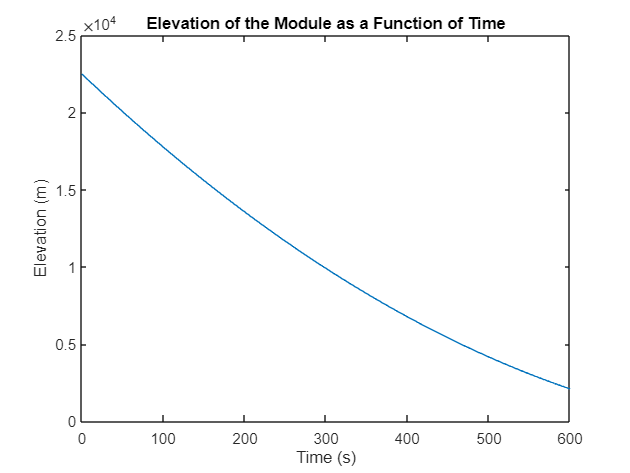


%c
v = v0;
e = 22500;
t = 0;
time = 0:h:t_final;
elevations = zeros(size(time));

for i = 1:length(time)
    elevations(i) = e;
    e = e + v * h;
    v = v + dvdt(v) * h;
end

figure;
plot(time, elevations);
title('Elevation of the Module as a Function of Time');
xlabel('Time (s)');
ylabel('Elevation (m)');


%BONUS
t_final = 1000;
v = v0;
e = 22500;
t = 0;
while e > 0 && t <= t_final
    e = e + v * h;
    v = v + dvdt(v) * h;
    t = t + h;
end

fprintf('The module reaches the lunar surface approximately at t = %.2f s\n', t);

The module reaches the lunar surface approximately at t = 748.00 s


Question 2

a

q is theta

Let u1 = q and u2 = dq/dt

du1/dt = u2

du2/dt = -(g/l)*u1-p*u2

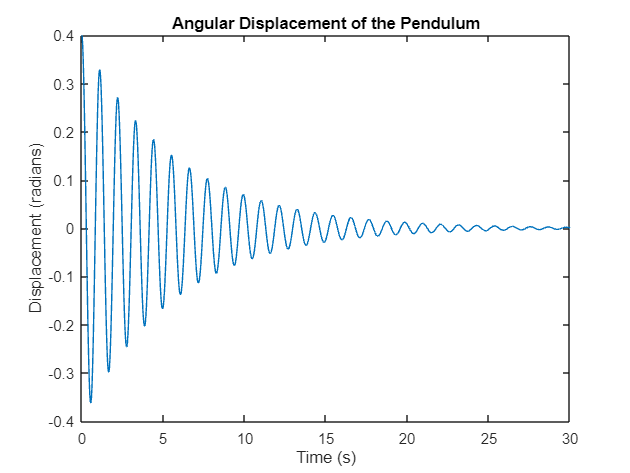

%b
g = 1.625; 
l = 0.05;  
p = 0.35;   
q0 = 0.4;  

f = @(t, u) [u(2); -g/l*u(1) - p*u(2)];

tspan = [0 30];
y0 = [q0; 0];  

[t, y] = ode45(f, tspan, y0);

figure;
plot(t, y(:, 1));
title('Angular Displacement of the Pendulum');
xlabel('Time (s)');
ylabel('Displacement (radians)');

Question 3

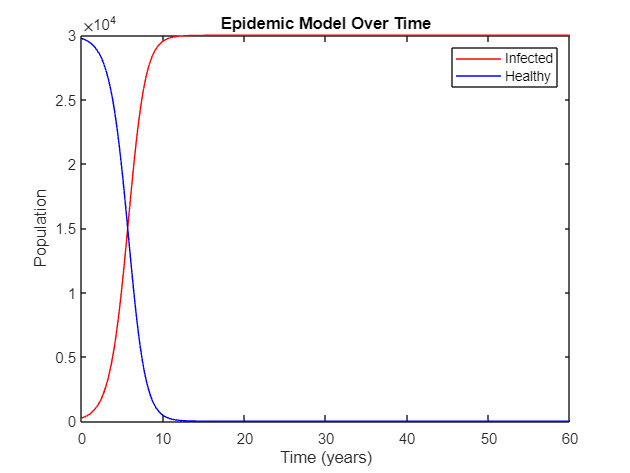

L = 30000;     
P0 = 250;     
k = 3e-5;   
h = 0.2;    
t_final = 60; 

P = P0;
t = 0;
time = 0:h:t_final;
infected = zeros(size(time));
healthy = zeros(size(time));

for i = 1:length(time)
    infected(i) = P;
    healthy(i) = L - P;
    P = P + h * k * P * (L - P);
end

figure;
plot(time, infected, 'r', time, healthy, 'b');
legend('Infected', 'Healthy');
title('Epidemic Model Over Time');
xlabel('Time (years)');
ylabel('Population');